% =========================================================================
% 扭矩誤差分析腳本 (Torque Error Analysis) - 過濾指定區間版
% 說明：過濾轉速 < 1000, 扭矩 < 20 的資料，獨立顯示 V0/V1 熱力圖
% =========================================================================

clear; clc; close all;

disp('正在讀取資料...');

正在讀取資料...


% 讀取舊版 (V0) 與新版 (V1) 資料
% V1 第二列為單位，使用 'NumHeaderLines' 跳過
opts_v0 = detectImportOptions('V0_500rpm_13000rpm_effMap_Report.csv', 'VariableNamingRule', 'preserve');
old_data = readtable('V0_500rpm_13000rpm_effMap_Report.csv', opts_v0);

opts_v1 = detectImportOptions('V1_500rpm_13000rpm_effMap_Report.csv', 'VariableNamingRule', 'preserve');
opts_v1.DataLines = [3, Inf]; % V1 第二行是單位，從第三行開始讀取數據
new_data = readtable('V1_500rpm_13000rpm_effMap_Report.csv', opts_v1);

% 提取需要的欄位
speed_old = old_data.SPEED;
trq_cmd_old = old_data.T_dem_E;
speed_new = new_data.SPEED;
trq_cmd_new = new_data.T_dem_E;

% 處理 V0 中可能出現的拼字錯誤 'torqe error'
if ismember('torqe error', old_data.Properties.VariableNames)
    err_old = abs(old_data.("torqe error"));
else
    err_old = abs(old_data.("torq error"));
end
err_new = abs(new_data.("torq error"));

% 確保轉換為數值陣列 (防止讀到字串)
if iscell(speed_old), speed_old = str2double(speed_old); end
if iscell(trq_cmd_old), trq_cmd_old = str2double(trq_cmd_old); end
if iscell(err_old), err_old = str2double(err_old); end
if iscell(speed_new), speed_new = str2double(speed_new); end
if iscell(trq_cmd_new), trq_cmd_new = str2double(trq_cmd_new); end
if iscell(err_new), err_new = str2double(err_new); end

% 過濾 NaN 缺失值或異常數值
valid_old = ~isnan(speed_old) & ~isnan(trq_cmd_old) & ~isnan(err_old);
speed_old = speed_old(valid_old); 
trq_cmd_old = trq_cmd_old(valid_old); 
err_old = err_old(valid_old);

valid_new = ~isnan(speed_new) & ~isnan(trq_cmd_new) & ~isnan(err_new);
speed_new = speed_new(valid_new); 
trq_cmd_new = trq_cmd_new(valid_new); 
err_new = err_new(valid_new);

disp('正在進行網格化處理...');

正在進行網格化處理...


% 設定容差以定義「操作點網格」(轉速 500 RPM, 扭矩 2 Nm)
tol_speed = 500; 
tol_trq = 2;

% 將所有數據映射到網格點上
op_old_grid = [round(speed_old / tol_speed) * tol_speed, round(trq_cmd_old / tol_trq) * tol_trq];
op_new_grid = [round(speed_new / tol_speed) * tol_speed, round(trq_cmd_new / tol_trq) * tol_trq];

% 找出共同涵蓋的操作點 (交集)
unique_op_old = unique(op_old_grid, 'rows');
unique_op_new = unique(op_new_grid, 'rows');
common_ops = intersect(unique_op_old, unique_op_new, 'rows');

% ==========================================
% [重要] 依照需求過濾指定工作範圍 (僅保留共同操作點中的部分)
% ==========================================
disp('正在過濾特定工作範圍 (Speed >= 1000, Torque >= 20)...');

正在過濾特定工作範圍 (Speed >= 1000, Torque >= 20)...



% 過濾共同操作點
keep_common = (common_ops(:,1) >= 1000) & (common_ops(:,2) >= 20);
common_ops = common_ops(keep_common, :);

% 利用 ismember 完整抓取屬於這些過濾後共同操作點的「所有數據」
idx_keep_old = ismember(op_old_grid, common_ops, 'rows');
aligned_speed_old = speed_old(idx_keep_old);
aligned_trq_old = trq_cmd_old(idx_keep_old);
aligned_err_old = err_old(idx_keep_old);
op_old_grid = op_old_grid(idx_keep_old, :); % 更新網格資料

idx_keep_new = ismember(op_new_grid, common_ops, 'rows');
aligned_speed_new = speed_new(idx_keep_new);
aligned_trq_new = trq_cmd_new(idx_keep_new);
aligned_err_new = err_new(idx_keep_new);
op_new_grid = op_new_grid(idx_keep_new, :); % 更新網格資料

fprintf('成功對齊！保留了舊版 %d 筆數據與新版 %d 筆數據進行公平比較。\n', sum(idx_keep_old), sum(idx_keep_new));

成功對齊！保留了舊版 79 筆數據與新版 80 筆數據進行公平比較。



%% 產生匯總對齊比較表 (使用交集資料)
num_ops = size(common_ops, 1);
avg_err_old_common = zeros(num_ops, 1);
avg_err_new_common = zeros(num_ops, 1);

for i = 1:num_ops
    op = common_ops(i, :);
    avg_err_old_common(i) = mean(aligned_err_old(op_old_grid(:,1) == op(1) & op_old_grid(:,2) == op(2)));
    avg_err_new_common(i) = mean(aligned_err_new(op_new_grid(:,1) == op(1) & op_new_grid(:,2) == op(2)));
end

improvement = avg_err_old_common - avg_err_new_common; 

summary_table = table(common_ops(:,1), common_ops(:,2), avg_err_old_common, avg_err_new_common, improvement, ...
    'VariableNames', {'SPEED_RPM', 'TORQUE_Nm', 'Old_Avg_Error', 'New_Avg_Error', 'Improvement_Nm'});
writetable(summary_table, 'aligned_summary_table.csv');

disp('開始繪圖...');

開始繪圖...


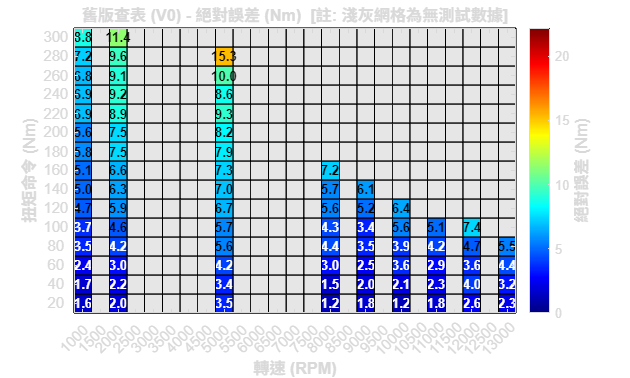


%% ==========================================
% 共用熱力圖準備資料 (僅涵蓋過濾後的共同點)
% ==========================================
% 強制轉速 X 軸以 500 RPM 為級距建立完整的等距向量 (從 1000 開始)
if isempty(common_ops)
    disp('警告：過濾後沒有任何共同的操作點可以繪圖。');
    return;
end

min_speed = 1000; % 強制從 1000 開始
max_speed = max(common_ops(:,1));
X_unique = (min_speed : 500 : max_speed)';

% 扭矩 Y 軸使用過濾後所有出現過的獨特扭矩
Y_unique = unique(common_ops(:,2));

% 取得網格的實際維度大小
Nx = length(X_unique);
Ny = length(Y_unique);

% 建立 NaN 空矩陣
Z_old_val = nan(Ny, Nx);
Z_new_val = nan(Ny, Nx);

% 填入資料 (因為現在只畫 common_ops，所以可以用迴圈直接填)
for i = 1:num_ops
    op = common_ops(i, :);
    row = find(Y_unique == op(2));
    col = find(X_unique == op(1));
    if ~isempty(row) && ~isempty(col)
        Z_old_val(row, col) = avg_err_old_common(i);
        Z_new_val(row, col) = avg_err_new_common(i);
    end
end

% 統一色階最大值
max_err = max([aligned_err_old; aligned_err_new]); 
if max_err == 0, max_err = 1; end
if isempty(max_err) || isnan(max_err), max_err = 1; end

%% ==========================================
% 圖表 1: 舊版誤差熱力圖 (獨立大圖)
% ==========================================
figure('Name', '舊版誤差熱力圖', 'Position', [100, 100, 1000, 600]); 
set(gcf, 'Color', 'w');

% 使用 1:Nx 與 1:Ny 絕對座標繪圖，確保色塊完美等比例且無偏移
h_img1 = imagesc(1:Nx, 1:Ny, Z_old_val);
set(gca, 'YDir', 'normal');
set(h_img1, 'AlphaData', ~isnan(Z_old_val)); 
% 設定背景色為較淺的灰色，減輕空缺網格的突兀感
set(gca, 'Color', [0.9 0.9 0.9]); 
colormap(jet); 
caxis([0, max_err]); 

% 標註數值 (絕對置中)
for i = 1:Ny
    for j = 1:Nx
        val = Z_old_val(i, j);
        if ~isnan(val)
            if val < max_err*0.2 || val > max_err*0.8
                t_col = 'w'; 
            else
                t_col = 'k'; 
            end
            text(j, i, sprintf('%.1f', val), ...
                 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
                 'Color', t_col, 'FontSize', 10, 'FontWeight', 'bold');
        end
    end
end

% 將 X 軸與 Y 軸的標籤替換回真實的轉速與扭矩數值
set(gca, 'XTick', 1:Nx, 'XTickLabel', X_unique);
set(gca, 'YTick', 1:Ny, 'YTickLabel', Y_unique);
xtickangle(45); % 轉速字若太長可旋轉 45 度避免重疊

xlabel('轉速 (RPM)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('扭矩命令 (Nm)', 'FontSize', 13, 'FontWeight', 'bold');
title('舊版查表 (V0) - 絕對誤差 (Nm)  [註: 淺灰網格為無測試數據]', 'FontSize', 15, 'FontWeight', 'bold');
cb1 = colorbar; cb1.Label.String = '絕對誤差 (Nm)'; cb1.Label.FontSize = 12; cb1.Label.FontWeight = 'bold';

% 關閉預設網格，繪製完美的邊界線 (剛好在 .5 的位置)
grid off;
hold on;
for x_edge = 0.5:(Nx+0.5)
    plot([x_edge x_edge], [0.5, Ny+0.5], 'Color', [0 0 0 0.2], 'LineWidth', 0.5);
end
for y_edge = 0.5:(Ny+0.5)
    plot([0.5, Nx+0.5], [y_edge y_edge], 'Color', [0 0 0 0.2], 'LineWidth', 0.5);
end
hold off;

xlim([0.5, Nx+0.5]);
ylim([0.5, Ny+0.5]);
set(gca, 'layer', 'top', 'FontSize', 11); 

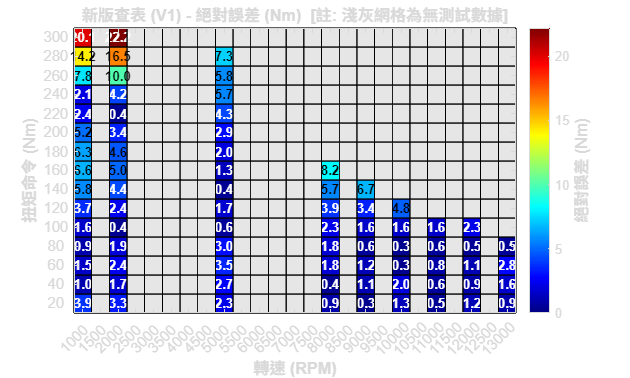


%% ==========================================
% 圖表 2: 新版誤差熱力圖 (獨立大圖)
% ==========================================
figure('Name', '新版誤差熱力圖', 'Position', [150, 150, 1000, 600]);
set(gcf, 'Color', 'w');

% 使用 1:Nx 與 1:Ny 絕對座標繪圖
h_img2 = imagesc(1:Nx, 1:Ny, Z_new_val);
set(gca, 'YDir', 'normal');
set(h_img2, 'AlphaData', ~isnan(Z_new_val));
set(gca, 'Color', [0.9 0.9 0.9]);
colormap(jet);
caxis([0, max_err]);

% 標註數值 (絕對置中)
for i = 1:Ny
    for j = 1:Nx
        val = Z_new_val(i, j);
        if ~isnan(val)
            if val < max_err*0.2 || val > max_err*0.8
                t_col = 'w'; 
            else
                t_col = 'k'; 
            end
            text(j, i, sprintf('%.1f', val), ...
                 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
                 'Color', t_col, 'FontSize', 10, 'FontWeight', 'bold');
        end
    end
end

% 將 X 軸與 Y 軸的標籤替換回真實的轉速與扭矩數值
set(gca, 'XTick', 1:Nx, 'XTickLabel', X_unique);
set(gca, 'YTick', 1:Ny, 'YTickLabel', Y_unique);
xtickangle(45);

xlabel('轉速 (RPM)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('扭矩命令 (Nm)', 'FontSize', 13, 'FontWeight', 'bold');
title('新版查表 (V1) - 絕對誤差 (Nm)  [註: 淺灰網格為無測試數據]', 'FontSize', 15, 'FontWeight', 'bold');
cb2 = colorbar; cb2.Label.String = '絕對誤差 (Nm)'; cb2.Label.FontSize = 12; cb2.Label.FontWeight = 'bold';

% 關閉預設網格，繪製完美的邊界線 (剛好在 .5 的位置)
grid off;
hold on;
for x_edge = 0.5:(Nx+0.5)
    plot([x_edge x_edge], [0.5, Ny+0.5], 'Color', [0 0 0 0.2], 'LineWidth', 0.5);
end
for y_edge = 0.5:(Ny+0.5)
    plot([0.5, Nx+0.5], [y_edge y_edge], 'Color', [0 0 0 0.2], 'LineWidth', 0.5);
end
hold off;

xlim([0.5, Nx+0.5]);
ylim([0.5, Ny+0.5]);
set(gca, 'layer', 'top', 'FontSize', 11); 


disp('分析完成！');

分析完成！
